# LAB3: Objects Tracking

## Done by hiba khayati

- VIDEO SEQUENCES READING

v = VideoReader('STGEORGES.avi');
videoPlayer = vision.VideoPlayer;
while hasFrame(v)
    videoFrame = readFrame(v);
    videoPlayer(videoFrame);
    pause(0.1)
end

           2. SOME TRANSFORMATIONS

              2.1 Transform the video images into grayscale images and play the video

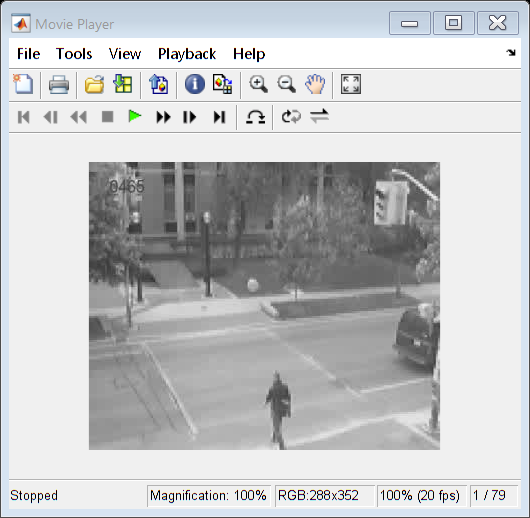

 v = VideoReader('STGEORGES.avi');% read video
 numImgs = get(v, 'NumFrames');% get number of frames in video
 frames = read(v);
 obj=VideoWriter('STGEORGES_gray.avi');% save new video
 open(obj);

 for i=1:numImgs
     movie(i).cdata=rgb2gray(frames(:,:,:,i));%convert each frame from rgb to grayscale
     movie(i).colormap=gray;
 end

 writeVideo(obj,movie);
 close(obj);
 vid = VideoReader('STGEORGES_gray.avi');
 x=read(vid);
 p=implay(x);% play the video as grayscale

              2.3 reducing the frame rate (/2)

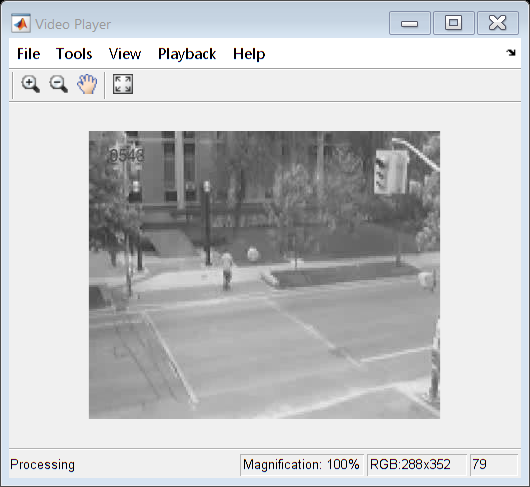

videoReader = VideoReader('STGEORGES_gray.avi');
videoPlayer = vision.VideoPlayer;
while hasFrame(videoReader)

   videoFrame = readFrame(videoReader);
    videoPlayer(videoFrame);
    pause(1/3) %Reducing the frame rate
end

           3. CREATE A VIDEO FROM A SET OF 2D IMAGES

vidObj = VideoWriter('outvideo.mp4','MPEG-4');

Cannot create file outvideo.mp4. Permission Denied.

open(vidObj);
for i=1:15
[Frame,map]=imread(strcat(num2str(i),'.bmp'));
if ~isempty(map)
        FramedImage = ind2rgb(Frame,map);
    end
currFrame=im2frame(FramedImage);
writeVideo(vidObj,currFrame);
end
close(vidObj);

The video is called outvideo.

4. OBJECTS TRACKING ON PIETON VIDEO SEQUENCE

I choose the Median Filter in this part which is a nonlinear operation often used in image processing to reduce "salt and pepper" noise. A median filter is more effective than convolution when the goal is to simultaneously reduce noise and preserve edges. 

 vid=VideoReader('outvideo.mp4');        %To read the video into the matlab.
implay('outvideo.mp4')                  %Displaying the video.

%"get()" is used to obtain some information about the video.
nframes = get(vid,'NumFrames');  
%%
for i=1:nframes
    frame= read(vid,i);      %reading the frame no. i
    img=rgb2gray(frame);     %converting the frame from"RGB"to"Gray Scale"
    img=medfilt2(img);       %Apllying Median Filter.
    img=im2bw(img);          %Converting the frame into Binary Image.
    bw = bwareaopen(img,100);
    img=imcomplement(img);   %Complementing the frame.
    img=imfill(img,'holes'); %fills the holes in the binary image BW.
    
    %Obtaining Some Properties about the frame(no. of objects detected,
    %Centroid.
    bw=bwlabel(img);
    props=regionprops(bw,'BoundingBox','Centroid');
    
    imshow(frame)             %Displaying the frame
    hold on                   %Fixing the frame
    
    % Drawing rectangles around the detected object.
    for j=1:length(props)
        bb=props(j).BoundingBox;
        bc=props(j).Centroid;
        
        
        rectangle('Position',bb,'EdgeColor','m','LineWidth',3)
        plot(bc(1),bc(2),'-r+')
    end
    hold off
end

The result was not satisfying. I coudn't track only pieton on the image, i tracked also other things with; and i tried to change regionprops parameters to only select the pieton but i coudn't do that.

5. CREATE SYNTHETIC IMAGES WITH MOVING OBJECTS

q=imread('D:\UPEC Assignments\Matlab\20.bmp');
r1=imrotate(q,180);
imwrite(r1,'D:\UPEC Assignments\Matlab\21.bmp');
imshow(r1);

vidobj=VideoWriter('D:\UPEC Assignments\Matlab\output.mp4','MPEG-4');
open(vidobj);

for i=1:21
    
    [a, thismap]=imread(strcat(num2str(i),'.bmp'));
    currFrame=im2frame(a, thismap);
    
    writeVideo(vidobj,currFrame);
end
close(vidobj)